% Загрузка файла и создание матрицы H из созданного датасета

% loaded_data = load('..\H_dataset_test_8_1_1024.mat');
loaded_data = load('..\H_dataset_test_32_1_128.mat');

H_dataset = loaded_data.H_dataset;
[num_samples, timeslots, num_tx_antennas, num_subcarriers] = size(H_dataset)

num_samples = 3

timeslots = 10

num_tx_antennas = 32

num_subcarriers = 128

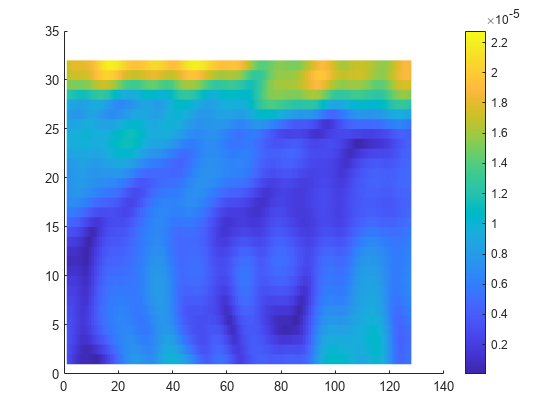


% Создание структуры для хранения метрик
metrics_results = struct();

%% DFT метод сжатия из статьи

method_name = 'DFTmethod_1';

% truncation_factors = 2:2:(num_subcarriers);
truncation_factors = linspace(2, num_subcarriers, 64);
percent_truncation = zeros(1, length(truncation_factors));
correlation_values = zeros(1, length(truncation_factors));
nmse_values = zeros(1, length(truncation_factors));

H_method_1 = squeeze(H_dataset(1,1,:,:));
figure; clf; hold on;
surf(abs(squeeze(H_method_1)), 'EdgeColor', 'none'); colorbar;

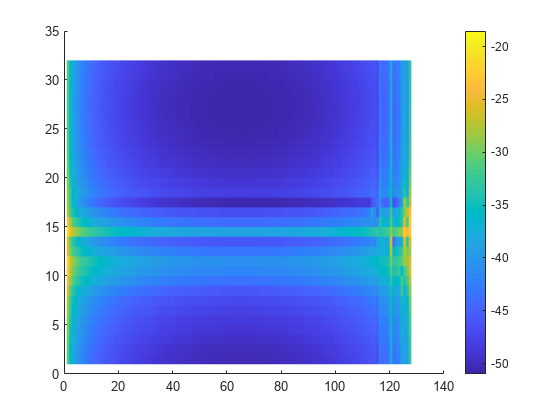

fft2_H_method_1 = fft2(H_method_1);
figure; clf; hold on;
surf(10*log10(abs(squeeze(fft2_H_method_1))), 'EdgeColor', 'none'); colorbar;

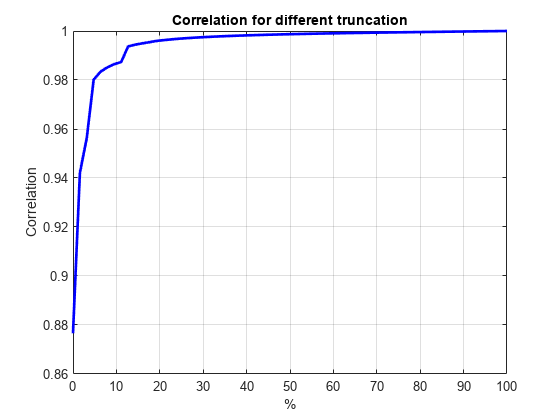


for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);
    midPoint = floor(num_subcarriers/2);
    lowerEdge = midPoint - (num_subcarriers-truncationFactor)/2 + 1;
    upperEdge = midPoint + (num_subcarriers-truncationFactor)/2;
    H_truncate_temp = fft2_H_method_1(:,[1:lowerEdge-1 upperEdge+1:end]);
    H_truncate = ifft2(H_truncate_temp);
    
    H_recover_temp = fft2(H_truncate);
    H_recover_zero = zeros(num_tx_antennas,num_subcarriers);
    H_recover_zero(:, [1:lowerEdge-1 upperEdge+1:end]) = H_recover_temp;
    H_recover(:, :) = ifft2(H_recover_zero);

    correlation_values(i) = hCorrelation(H_recover, H_method_1);
    nmse_values(i) = hNMSE(H_recover, H_method_1);
    % Рассчитываем процент для truncationFactor
    percent_truncation(i) = (truncationFactor - 2) / (num_subcarriers - 2) * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;


% Вывод результатов
% Correlation
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

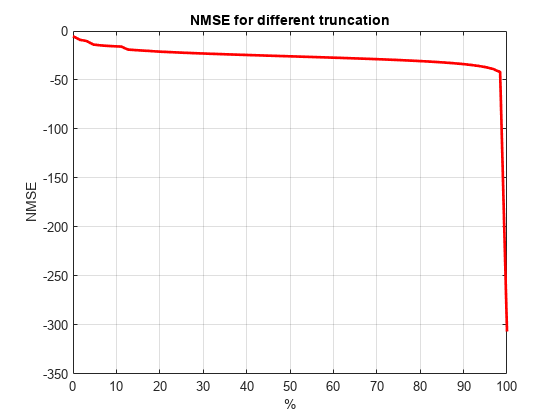


% NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;


clear method_name truncation_factors percent_truncation correlation_values nmse_values


method_name = 'DFTmethod_2';

truncation_factors = linspace(0, 0.999, 64);
percent_truncation = zeros(1, length(truncation_factors));
correlation_values = zeros(1, length(truncation_factors));
nmse_values = zeros(1, length(truncation_factors));

H_method_2 = squeeze(H_dataset(1,1,:,:));

fft2_H_method_2 = fft2(H_method_2);

% Обнуление всех малых коэффициентов и обратное преобразование

fft2_H_sort = sort(abs(fft2_H_method_2(:))); % Сортировка по величине

for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);
    thresh = fft2_H_sort(floor((1-truncationFactor)*length(fft2_H_sort)));
    ind = abs(fft2_H_method_2)>thresh; % Поиск малых индексов по пороговому
    H_truncate_temp = fft2_H_method_2.*ind; % Отсечение малых значений по маске
    
    H_truncate=ifft2(H_truncate_temp);

    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(H_truncate, H_method_2);
    nmse_values(i) = hNMSE(H_truncate, H_method_2);
    % Сохраняем процент отсечения для каждого значения truncation
    percent_truncation(i) = truncationFactor * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;


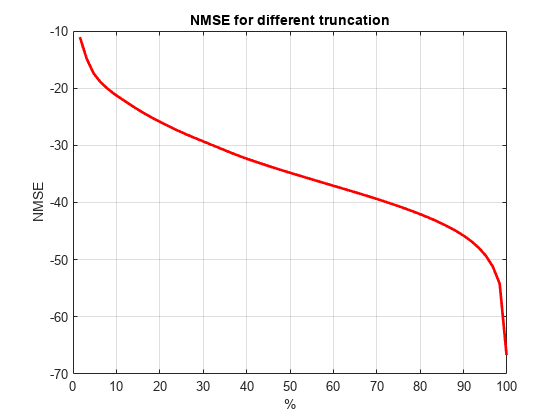

% Построение графика для NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

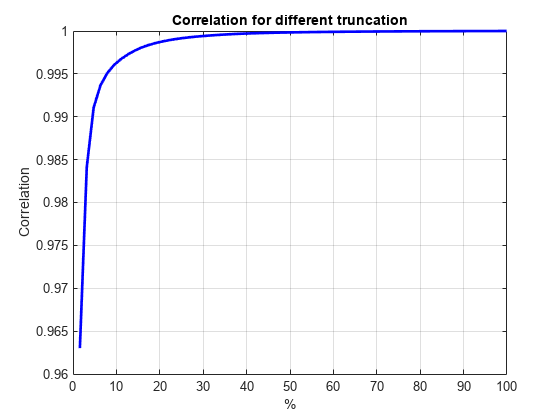

% Построение графика для корреляции
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;


clear method_name truncation_factors percent_truncation correlation_values nmse_values

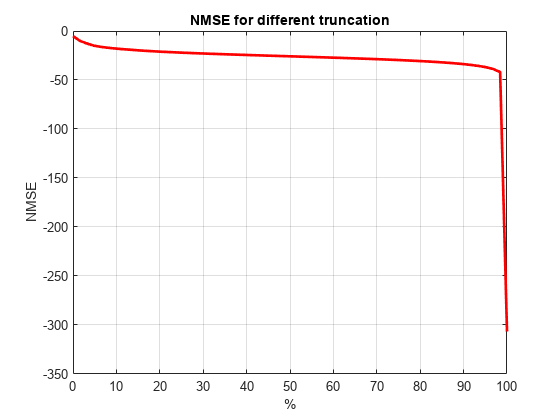

method_name = 'DFTmethod_3';

H_method_3 = squeeze(H_dataset(1,1,:,:));

fft2_H_method_3 = fft2(H_method_3);

truncation_factors = linspace(2, num_subcarriers, 64);
percent_truncation = zeros(1, length(truncation_factors));
correlation_values = zeros(1, length(truncation_factors));
nmse_values = zeros(1, length(truncation_factors));

for i = 1:length(truncation_factors)
    truncationFactor = truncation_factors(i);

    norms_sum = sum(abs(fft2_H_method_3(:,:)),1);
    [sorted_norms,sorted_index] = sort(norms_sum, "descend");
    select_index = sort(sorted_index(1:truncationFactor));
    % Создание новой матрицы c пороговым значением и её усечение
    H_truncate_temp = fft2_H_method_3(:,select_index);
    H_truncate = ifft2(H_truncate_temp);

    % Создание вектра позиций сохранённных элементов
    zero_vector = zeros(1, num_subcarriers);
    zero_vector(select_index) = 1;
    

    H_recover_temp = fft2(H_truncate);
    H_recover_zero = zeros(num_tx_antennas,num_subcarriers);

    fill_rows = zero_vector == 1;
    H_recover_zero(:, fill_rows) = H_recover_temp;
    H_recover(:, :) = ifft2(H_recover_zero);

    % Сохранение значений метрик
    correlation_values(i) = hCorrelation(H_recover, H_method_3);
    nmse_values(i) = hNMSE(H_recover, H_method_3);
    % Сохраняем процент отсечения для каждого значения truncation
    percent_truncation(i) = (truncationFactor - 2) / (num_subcarriers - 2) * 100;
end
% Сохраняем результаты в структуру
metrics_results.(method_name).truncation_factors = truncation_factors;
metrics_results.(method_name).percent_truncation = percent_truncation;
metrics_results.(method_name).correlation_values = correlation_values;
metrics_results.(method_name).nmse_values = nmse_values;

% Построение графика для NMSE
figure;
plot(percent_truncation, nmse_values, 'r-', 'LineWidth', 2);
xlabel('%');
ylabel('NMSE');
title('NMSE for different truncation');
grid on;

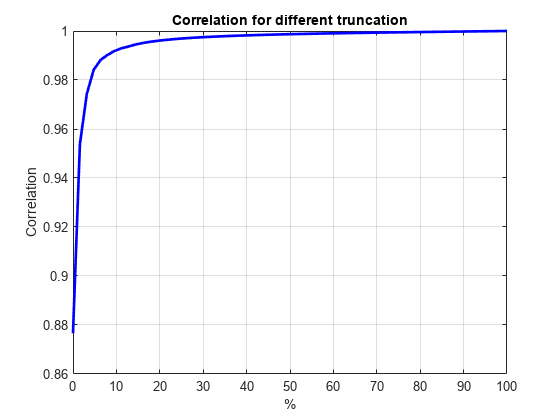


% Построение графика для корреляции
figure;
plot(percent_truncation, correlation_values, 'b-', 'LineWidth', 2);
xlabel('%');
ylabel('Correlation');
title('Correlation for different truncation');
grid on;

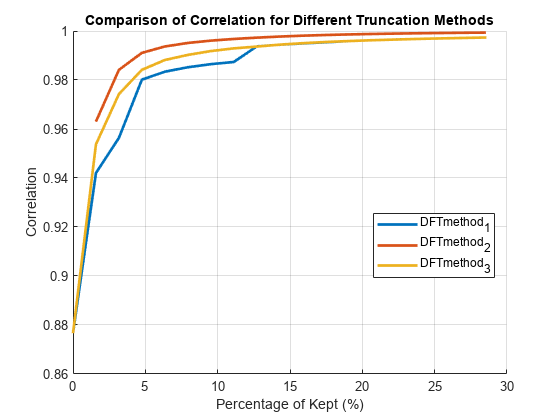


clear method_name truncation_factors percent_truncation correlation_values nmse_values

% Определение максимального процента для отображения
max_percent = 30; % Например, отображаем только до 50%

% Создание новой фигуры для общего графика корреляции
figure;
hold on;
methods = fieldnames(metrics_results);
% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    percent_truncation = metrics_results.(method_name).percent_truncation;
    correlation_values = metrics_results.(method_name).correlation_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = percent_truncation <= max_percent;

    % Построение графика для корреляции
    plot(percent_truncation(valid_indices), correlation_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('Percentage of Kept (%)');
ylabel('Correlation');
title('Comparison of Correlation for Different Truncation Methods');
grid on;
legend('Location', 'best');
% Ограничение оси x до максимального процента
xlim([0, max_percent]);

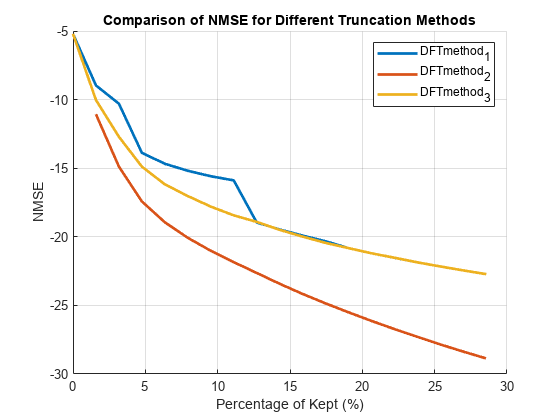


% Создание новой фигуры для общего графика NMSE
figure;
hold on;

% Перебор всех методов в структуре
for method_idx = 1:numel(methods)
    method_name = methods{method_idx};
    
    % Получение данных для текущего метода
    percent_truncation = metrics_results.(method_name).percent_truncation;
    nmse_values = metrics_results.(method_name).nmse_values;
    
    % Находим индексы, соответствующие проценту до max_percent
    valid_indices = percent_truncation <= max_percent;
    
    % Построение графика для NMSE
    plot(percent_truncation(valid_indices), nmse_values(valid_indices), '-', 'LineWidth', 2, 'DisplayName', method_name);
end

% Настройка осей и меток
xlabel('Percentage of Kept (%)');
ylabel('NMSE');
title('Comparison of NMSE for Different Truncation Methods');
grid on;
legend('Location', 'best');

% Ограничение оси x до максимального процента
xlim([0, max_percent]);

 Вспомогательные функции

function rho = hCorrelation(in,out)
% RHO = hCSICorrelation(X,Y) возвращает линейную корреляцию между X и Y.

n1 = sqrt(sum(conj(in).*in,'all'));
n2 = sqrt(sum(conj(out).*out,'all'));
aa = abs(sum(conj(in).*out,'all'));
rho = aa / (n1*n2);
end

function nmse = hNMSE(in,out)
% NMSE = helperNMSE(X,Y) возвращает нормализованную среднюю квадратичную ошибку (NMSE) между X и Y. 

mse = mean(abs(in-out).^2,'all');
nmse = 10*log10(mse / mean(abs(in).^2,'all'));
end